# Signal Analysis

In this exercise, you are going to learn how to make a sinusoidal signal and learn what a sampling frequency is. You'll further your programming skills and learn a simple animation technique and how to produce sounds from your computer. 

% DO NOT CHANGE ANYTHING HERE
clear; clc;

Follow the instructions carefully.

#### TASK 1. Making a Sine Function

It is important to UNDERSTAND, and not just to know, how to numerically set up a period function. The easiest function we can make is a sine function. We've already done this before in one of the previous exercises. Let's see if you remember. 

Define the frequency of oscillation. Initially set the frequency to $261.63$ $Hz$. Solve for the period of oscillation in terms of the frequency of oscillation.

f = 261.63;     % Hertz
T = 1/f;        % seconds

You want to plot a sine function showing only $n$ periods of oscillation. How do you do that?

First, let us define $n$, where $n$ is the number of periods and is an integer number. Let its value be equal to 2.

n = 2;

Next, we define the range of time. Use the variable $t$ and define its range from $t=0$ to a maximum time of $n$ period(s), with a step size of one-hundredths of a period.

t = 0:T/100:n*T;

How many data points does the variable $t$ have? Your answer should be the output of a written code.

length(t)

ans = 201

The sine function is given by the equation $y=A\;\sin \left(\omega t\right)$, where $A$ is the amplitude of the function and $\omega$ is the angular frequency and is equal to $2 \pi f$. Write down the code for making a sine function using the earlier defined variables. For simplicity, you may ignore $A$ or let $A=1$.

y = sin(2*pi*f*t);

Plot the sine function versus time. Use black circles as markers. Add an appropriate x- and y-axes labels.

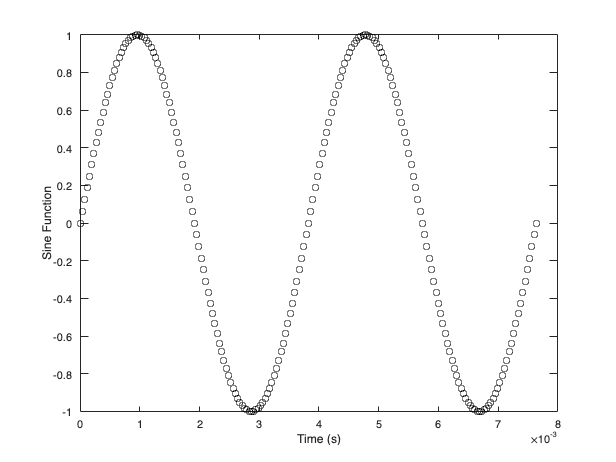

plot(t,y,'ko')
xlabel('Time (s)')
ylabel('Sine Function')

In some instances, it is more appropriate to use the radian scale instead of a time scale in order to determine the number of cycles. Replot the sine function, in this case, versus the variable $x$, where $x$ is in units of $radians$ or $pi$s. You will need to express $x$ in terms of the time variable, $t$. Add an appropriate x- and y-axes labels.

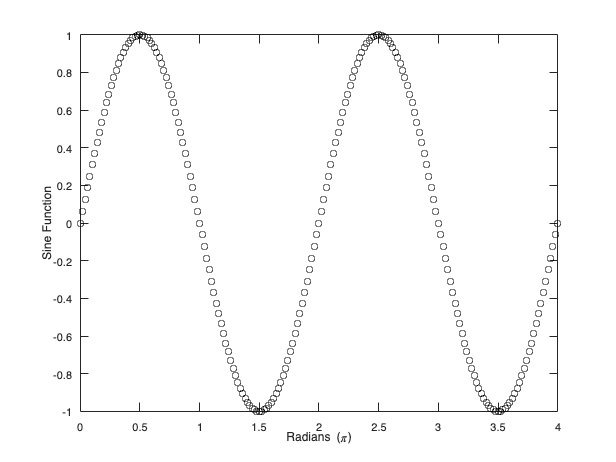

x = 2*f*t;
plot(x,y,'ko')
xlabel('Radians (\pi)')
ylabel('Sine Function')

This type of plot is also a sine function versus angular frequency plot. Use the "Slider" feature of the Live Editor, setting the variable $n$ from 1 to 10. There is no need to rerun this section. Livescript will immediately process your graphs. 

#### TASK 2. Animate your sine function.

Let's add a phase to your sine function, such that $y=A\;\sin \left(\omega t+\phi \right)$. Note that the unit of the phase angle, $\phi$, is $radians$. 

Define the phase angle, $\phi$, to be equal to a hundredth of $\pi$. Use the variable $phi$ for the phase angle, $\phi$.

% Field 1
%phi = -60/100;

Write down the sine function, $y$, with the given phase angle. Again, ignore the amplitude $A$.

% Field 2
% y = sin(2*pi*f*t + phi);

Plot two periods of the corresponding sine function versuse angular frequency. Use black circles as markers. Add corresponding and appropriate x- and y-labels.

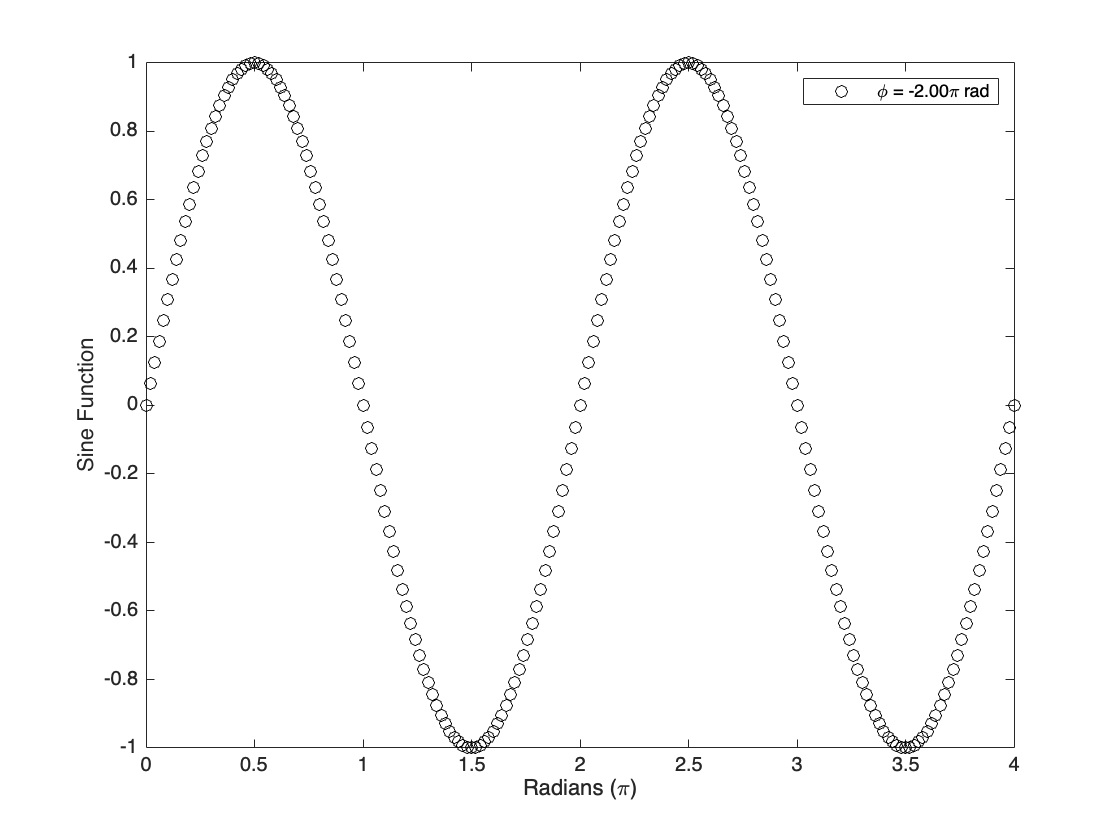

% Field 3
for i = 0:-10:-200
    phi = pi*i/100;
    y = sin(2*pi*f*t + phi);
    plot(x,y,'ko')
    xlabel('Radians (\pi)')
    ylabel('Sine Function')
    legend(['\phi = ' sprintf('%2.2f', phi/pi) '\pi rad'])
    pause(0.2)
end

Use the "Slider" feature to change the value of the phase angle from -200/100 to +200/100. Slowly, increase its value from 0/100 to +200/100 i steps of 10/100 and watch what happens. Then, slowly, decrease its value from 0/100 to -200/00 and observe what happens.

Which direction is the function moving as you increase the phase angle?

% Write your answer here

Which direction is the function moving as you decrease the phase angle?

% Write your answer here

Comment out your code in Field 1. 

Copy the equation for the sine function $y$ from Field 2 to Field 3 before the $plot()$ function. Comment out your code in Field 2. 

Before the equation for the sine function, $y$, type down the value of the phase angle, $\phi$, to be equal to $phi = i \pi /100$.

Make a $for$ loop to include all of the command lines in Field 3 using the index $i$ beginning from 0 to 200 with a step size of 10. 

You can use the legend command to add legends to the plot. Copy and paste this command line

%     legend(['\phi = ' sprintf('%2.2f', phi/pi) '\pi rad'])

after the $ylabel()$ function, without the comment operator %. If you don't understand what %2.2 means, try changing these numbers, e.g., 2.0, 2.4, 3.2, etc., and see what happens. The f simply means it's a floating point or non-integer number.

After the $legend()$ command, add the $pause()$ function. The argument of the pause function is the delay time in seconds. Use a delay time of 0.2 seconds.

Now change the values of the index $i$ to begin from -200 to 0, using the same step size. Run this section again.

Will you see the same effect if you assigned the index $i$ to begin from 0 and end at -200 with a step size of -10? Explain your answer.

% Write your answer here

#### TASK 3. Learning About the Sampling Frequency

In this task, you'll learn what the sampling frequency is and what the minimum sampling frequency should be. In any experiment, whenever data is gathered, the equipment that you use samples the signal at a specific rate. This rate is called the sampling frequency or sampling rate. If the sampling frequency is too low, it does not duplicate the actual signal. 

In the field below, make six subplots (three rows, two columns) using a $for$ loop. Within the $for$ loop, write a code that plots a sine function versus time with a frequency of $261,63$ $Hz$ displaying two periodic cycles for each subplot. This time use black solid lines with the default line widths. All of the figures should be completely identical. You may place the variables that doesn't need to be in the $for$ loop outside and before the $for$ loop, to make your code more time and memory efficient.

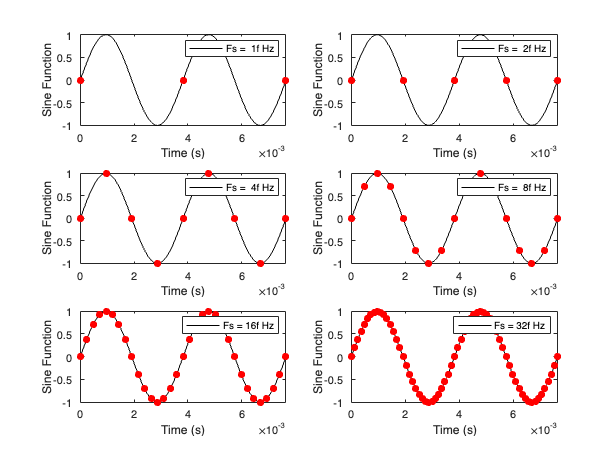

f = 261.63;     % Hertz
T = 1/f;        % seconds
t = 0:T/100:2*T;
Fs = [1, 2, 4, 8, 16, 32]*f;
for i = 1:6
    subplot(3,2,i)
    y = sin(2*pi*f*t);
    plot(t,y,'k')
    hold on
    ts = 0:1/Fs(i):2*T;
    ys = sin(2*pi*f*ts);
    plot(ts,ys,'ro',"MarkerFaceColor",'r')
    hold off
    xlabel('Time (s)')
    ylabel('Sine Function')
    legend(['Fs = ' sprintf('%2.0f', Fs(i)/f) 'f Hz'])
    xlim([0 2*T])
end

You are now going to define a second sine function and assign it to the variable $ys$. You will need to set-up its corresponding time variable, $ts$, first. This time variable will have a range from 0 to twice the period, $T$, the same as in the variable $t$. However, the step size is different. Using the step size as $1/Fs(i)$, write the code for $ts$ and $ys$ and place them inside the $for$ loop after the $plot()$ function for $(t,y)$.

Let's now define the variable $Fs$. This variable is called the sampling rate or the sampling frequency. Outside and before the $for$ loop, create an array/matrix with values, 1, 2, 4, 8, 16 and 32, in that order, times the frequency, $f$. This means that 1$f$ corresponds to sampling rate once per period. The value 8$f$ corresponds to a sampling rate of 8 times per period. Assign this array/matrix to the variable $Fs$. 

You need to plot $(ts,ys)$. Add another $plot()$ function for $(ts,ys)$. Use red solid circles as markers. You may need to use the option "MarkerFaceColor" in the $plot()$ function. Don't forget to use the $hold$ $on$ and $hold$ $off$commands. 

Finally, add an appropriate legend for each of the plots.

Run this section. If you don't see any difference between the graphs, add a $clear$ command at the very beginning of the field. This is what you're aiming for.

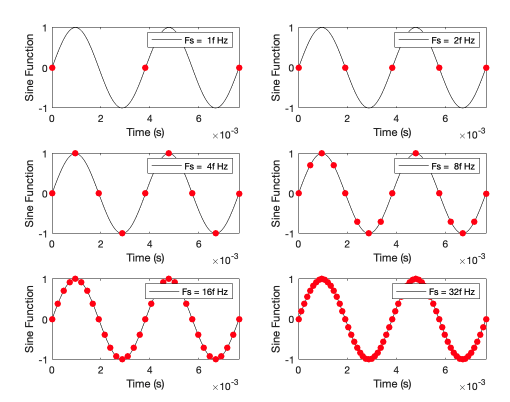

Of the six sampling rates above, what is the minimum sampling rate that duplicates the actual signal?

% Write your answer here


#### TASK 4. Producing Sound in MATLAB

In the field below, write a code that will generate a sine function as a function of time with a frequency of $261.63$ $Hz$. This frequency corresponds to the middle $C$ note, or $C_4$ to be more specific. Let the sampling frequency be equal to 32$f$. Assign the variable $Fs$ to the value 32. The time scale should be from 0 to 3, with a step size equal to the sampling frequency. This means that the audio is going to be played for 3 seconds. Use the command $clf$ or $figure$ at the beginning of the field to refresh and make a new figure. Use a solid black line, to plot the function. Add appropriate x- and y-axes labels. If you haven't yet, add the command $xlim()$ and limit the x-axis scale to two cycles.

clear; figure;
f = 261.63;     % Hertz
T = 1/f;        % seconds
Fs = 32

Fs = 32

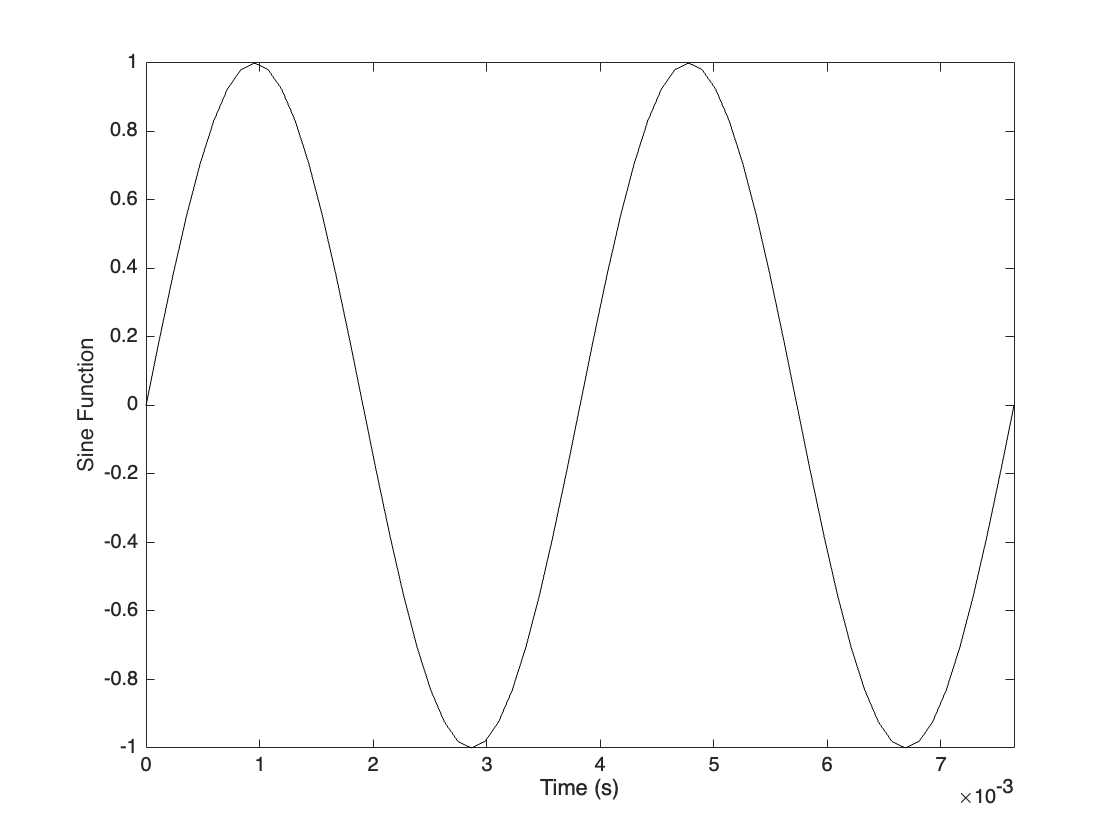

t = 0:T/Fs:3;
y = sin(2*pi*f*t);
plot(t,y,'k')
xlabel('Time (s)')
ylabel('Sine Function')
xlim([0 2*T])

Turn on your speakers, turn up the volume, and play the sound on computer.

% DO NOT CHANGE ANYTHING IN THIS FIELD
length(y)/(Fs*f) % play length in seconds

ans = 3.0001

soundsc(y,(Fs*f))

Try changing the frequency, $f$, to various notes. You can find the corresponding frequencies to all notes in this website: https://pages.mtu.edu/~suits/notefreqs.html